mydata = load('RSdata.mat')

mydata = struct with fields:
            rt_tout: [1600×1 double]
      rt_ScopeData4: [1×1 struct]
    rt_motor_speeds: [1×1 struct]
               rt_u: [1×1 struct]
               rt_v: [1×1 struct]
               rt_w: [1×1 struct]
        rt_pressure: [1×1 struct]
    rt_z_ultrasonic: [1×1 struct]
             rt_a_x: [1×1 struct]
             rt_a_y: [1×1 struct]
             rt_a_z: [1×1 struct]
               rt_p: [1×1 struct]
               rt_q: [1×1 struct]
               rt_r: [1×1 struct]



%ms = mydata.rt_motor_speeds.signals.values;

% u = mydata.rt_optical_flow.signals.values(:,1);
% v = mydata.rt_optical_flow.signals.values(:,2);
% w = mydata.rt_optical_flow.signals.values(:,3);
u = mydata.rt_u.signals.values;
v = mydata.rt_v.signals.values;
w = mydata.rt_w.signals.values;
a_x = mydata.rt_a_x.signals.values;
a_y = mydata.rt_a_y.signals.values;
a_z = mydata.rt_a_z.signals.values;
p = mydata.rt_p.signals.values;
q = mydata.rt_q.signals.values;
r = mydata.rt_r.signals.values;
p_0 = mydata.rt_pressure.signals.values;
z_us = mydata.rt_z_ultrasonic.signals.values;

all_data = [u, v, w, a_x, a_y, a_z, p, q, r, p_0, z_us];
labels = ["u", "v", "w", "a_x", "a_y", "a_z", "p", "q", "r", "p_0","z_us"];

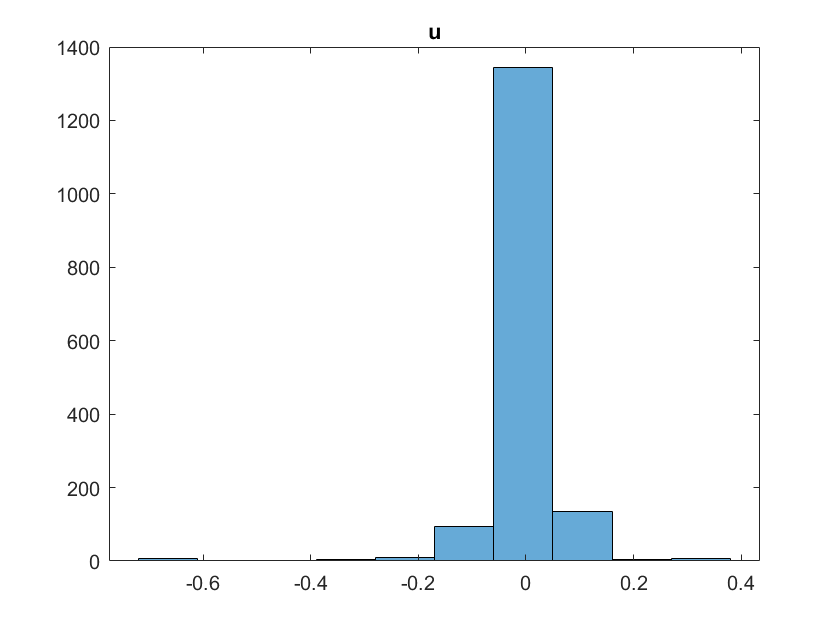

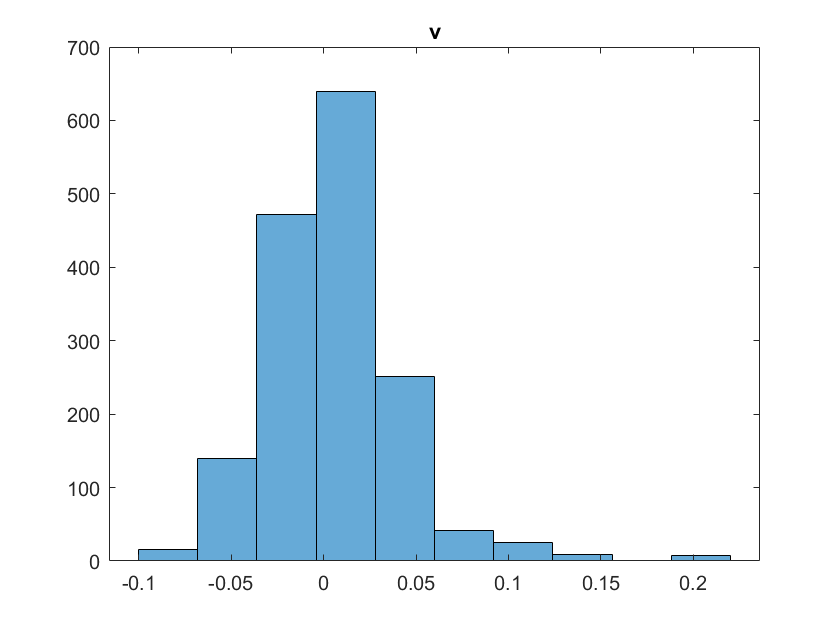

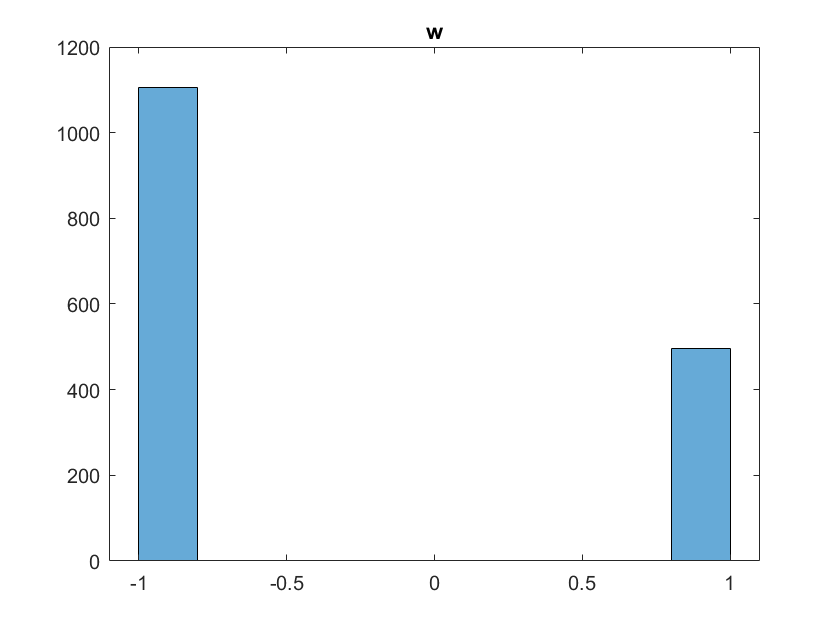

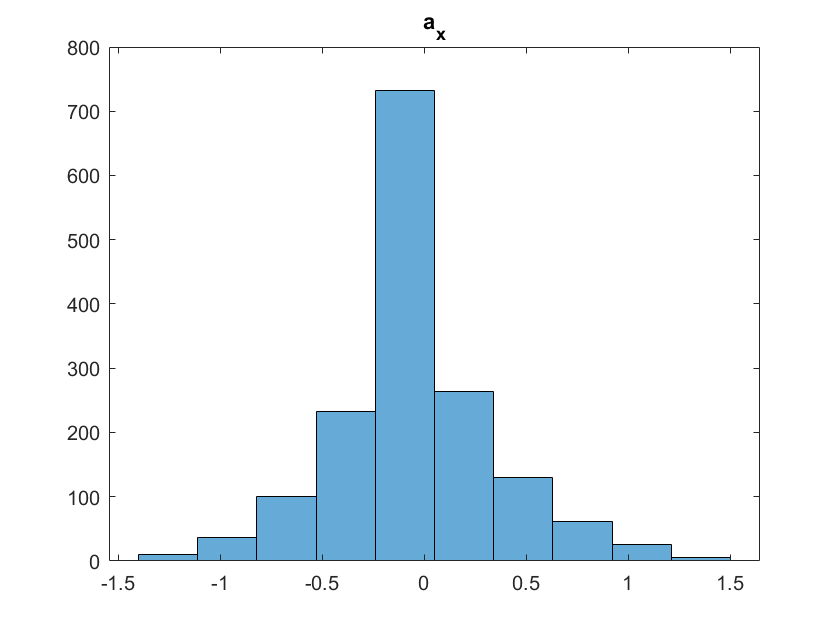

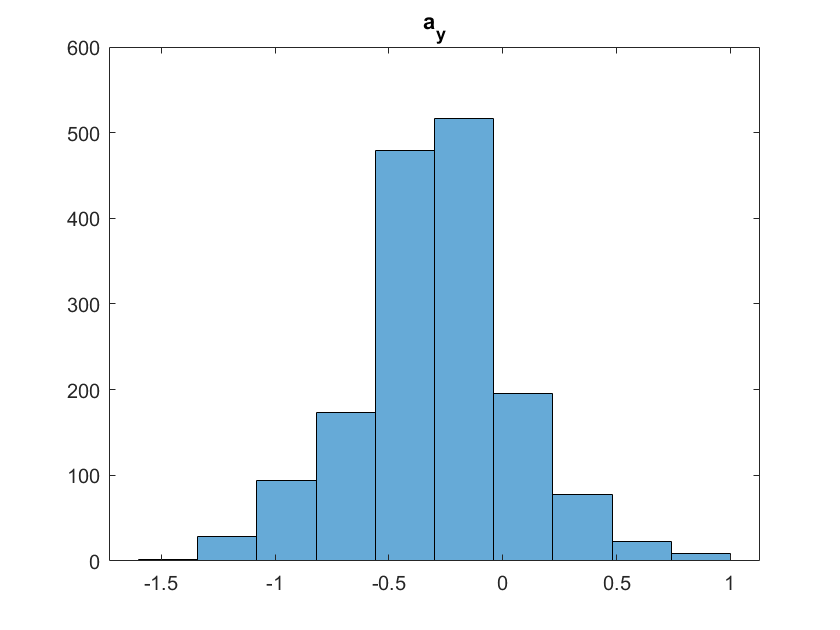

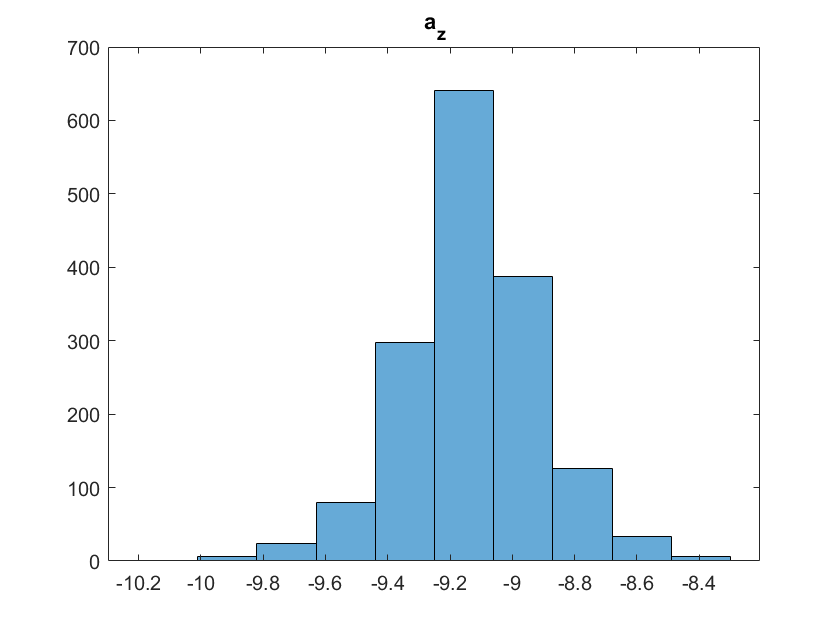

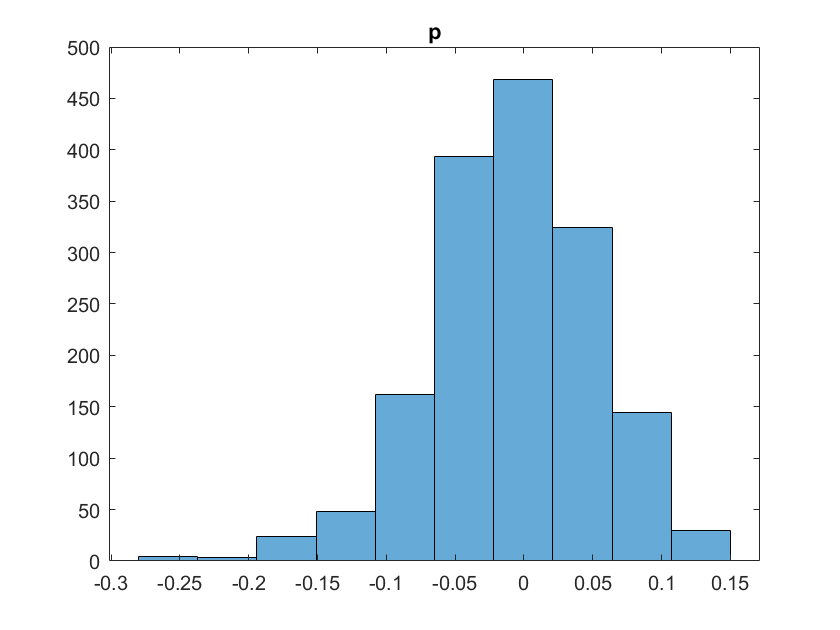

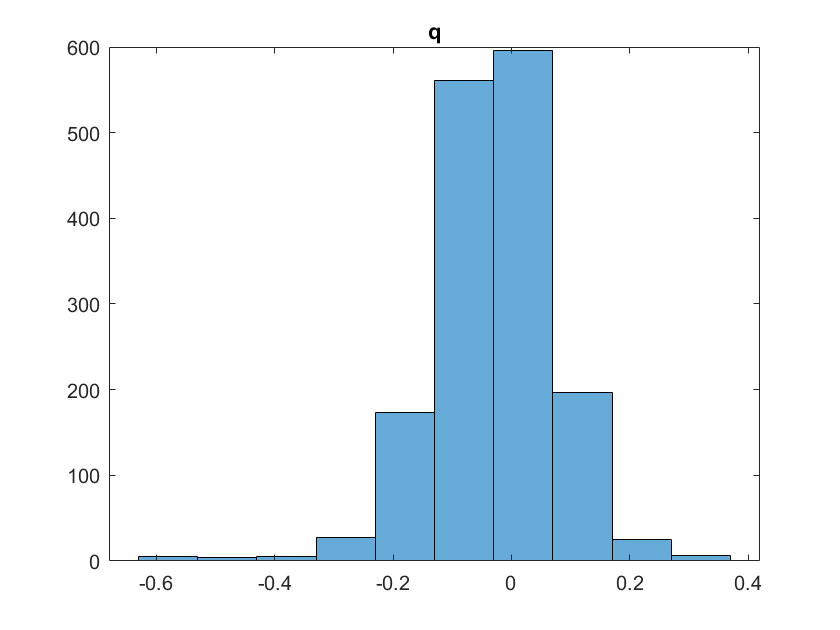

means = zeros(1,size(all_data,2));
covariances = cov(all_data);

for i=1:size(all_data,2)
    means(i) = mean(all_data(:,i));
    figure;
    histogram(all_data(:,i),10)
    title(labels(i))
end


g = 9.8; % acceleration due to gravity m/s^2
M_air = 0.0289644; % molar mass of air in kg/mol
R = 8.31432; % universal gas constant Nm/mol/k
p0 = 101325 % Pa standard pressure

p0 = 101325

T_kelvin =288.15;  % Assumed temperature in kelvin
K =-g*M_air/R/T_kelvin;
dt = 1/200;
Kappa = 1;


z_hypsometric =@(P) 1/K.*log(P./p0)

z_hypsometric = function_handle with value:
    @(P)1/K.*log(P./p0)


p_0_mean = mean(p_0)

p_0_mean = single
9.9584e+04

difference = z_hypsometric(p_0) - z_hypsometric(p_0_mean)

difference = 1600×1 single column vector
   -0.7058
   -0.7017
   -0.7017
   -0.7017
   -0.9111
   -0.9111
   -0.9111
   -0.7621
   -0.7621
   -0.7621


p_cov = cov(difference) %p_0

p_cov = single
0.2022

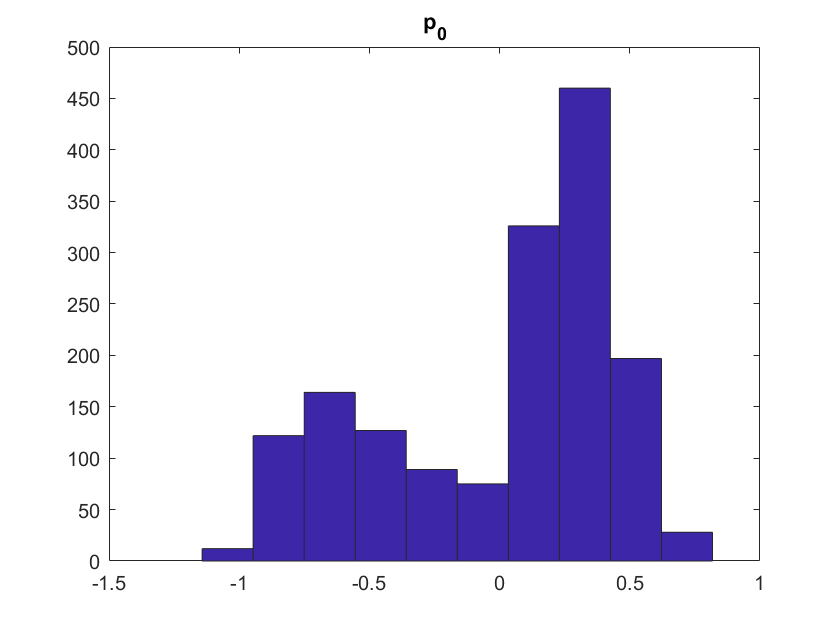

hist(difference)
title("p_0")


for i = 1:10
    for j = i:10
        correlation = corr(all_data(:,i),all_data(:,j));
        if abs(correlation) > 0.3 && (i ~= j)
            fprintf('Correlation between %s and %s is %f \n',labels(i),labels(j),corr(all_data(:,i),all_data(:,j)))
        end
    end
end

Correlation between u and v is 0.375495 
Correlation between u and q is 0.379745 
Correlation between a_x and a_y is -0.595192 
Correlation between a_y and p_0 is -0.340007 
Correlation between p and r is -0.548466 
Correlation between q and r is 0.347411 


corr_matrix = corrcoef(all_data);



A_e_dis = expm(A_elevator(1:2,1:2).*dt);
B_e_dis = A_elevator(1:2,3).* dt; 
C_e_dis = eye(2);

A_a_dis = expm(A_aileron(1:2,1:2).*dt);
B_a_dis = A_aileron(1:2,3).* dt; 
C_a_dis = eye(2);

q_cov = covariances(8,8);
p_cov = covariances(7,7);
Q_e_dis = q_cov*dt*eye(2);
Q_a_dis = p_cov*dt*eye(2);

theta_estimate = atan(-a_x./sqrt(a_y.^2 + a_z.^2));
phi_estimate = atan(a_y./a_z);
v_estimate = 1*z_us.*v;

%R_e = cov([u theta_estimate])
%R_a = cov([v phi_estimate])
R_e = [var(u) 0; 0 var(theta_estimate)]

R_e = 2×2 single matrix
    0.0042         0
         0    0.0018


R_a = [var(v_estimate) 0; 0 var(phi_estimate)]

R_a = 2×2 single matrix
    0.0003         0
         0    0.0015


A_t_dis = expm(A_throttle.*dt);
B_t_dis = B_throttle.*dt;
C_t_dis = [1 0];

a_z_cov = covariances(6,6);
z_us_cov = covariances(11,11);
r_cov = covariances(9,9);

Q_t_dis = [0 0;
           0 a_z_cov*dt];
R_t = z_us_cov;

A_r_dis = expm(A_rudder.*dt);
B_r_dis = B_rudder.*dt;
C_r_dis = [1 0];

Q_r_dis = r_cov*dt*eye(2);
R_r = eye(2);